Masas

d1 = 40.025/100; %m
d2 = 18.28/100; %m
h1=2.2/100;
h2=1.5/100;
b1=0.4/100;
b2=0.4/100;
density=2700;%kg/m3
m1=d1*h1*b1*density

m1 = 0.0951

m2=d2*h2*b2*density

m2 = 0.0296

Movimiendo

syms w t Ta x_home y_home
escala=1;
orientacion=180;
o_rad=-orientacion*pi/180;
A = 0.01875*escala;
phi = 3*o_rad;

r = A*(3+cos((3*((w*(t-(Ta)))+(0)))+phi));

x = r*cos(((w*(t-(Ta)))+(0))) + 0.2;
y = r*sin(((w*(t-(Ta)))+(0))) + 0.4;

v_x = diff(x,t);
v_y = diff(y,t);

v = sqrt(v_x^2+v_y^2);

a_x = diff(v_x,t);
a_y = diff(v_y,t);

theta_2 = -acos((x^2+y^2-d1^2-d2^2)/(2*d1*d2));
omega_2 = diff(theta_2,t);
alpha_2 = diff(omega_2,t);

theta_1 = atan(y/x) - atan(d2*sin(theta_2)/(d1+d2*cos(theta_2)));
omega_1 = diff(theta_1,t);
alpha_1 = diff(omega_1,t);

## Asignación de w y t

pa=10

pa = 10

Ta=5;
p=100;
a = 2*pi;
T = 16;
dt=16/p;
t = linspace(Ta,T+Ta,p);
w = a/(T);
v_min = 0.01; %m/s
v_max = 0.1; %m/s
%wm = mean([v_min,v_max])/mean(eval(r));
xe=eval(x);
ye=eval(y);
theta_1e=eval(theta_1);
theta_2e=eval(theta_2);

## Posición de HOME

x_home = 0.09; %m
y_home = 0.2072; %m
h_home = sqrt(d1^2-(x_home/2)^2);

theta_2_home = -acos((x_home^2+y_home^2-d1^2-d2^2)/(2*d1*d2))

theta_2_home = -2.9148

theta_1_home = atan(y_home/x_home) - atan(d2*sin(theta_2_home)/(d1+d2*cos(theta_2_home)))

theta_1_home = 1.3440

## Aproximacion

pa=10

pa = 10

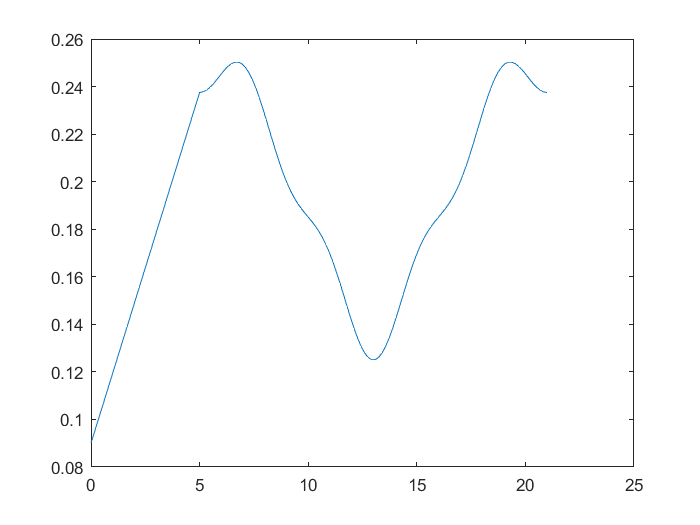

Ta=5;
dta=Ta/pa;
ta=linspace(0,Ta,pa);
%d_a_x=x_ev(1)-x_home
%pa_x=d_a_x/10
xa=linspace(x_home,xe(1),pa);
ya=linspace(y_home,ye(1),pa);
px=[xa,xe];
tie=[ta,t];
plot(tie,px)

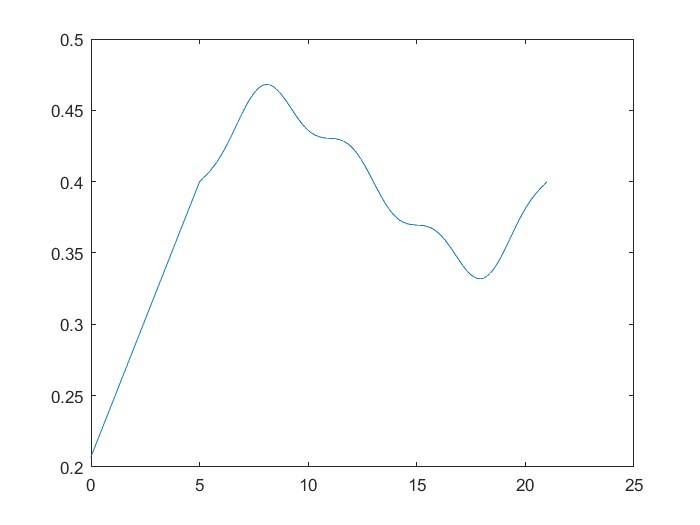

py=[ya,ye];
plot(tie,py)

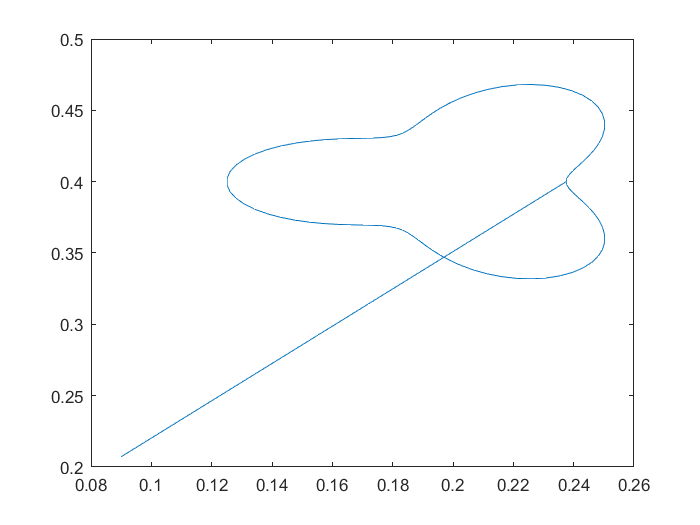

plot(px,py)

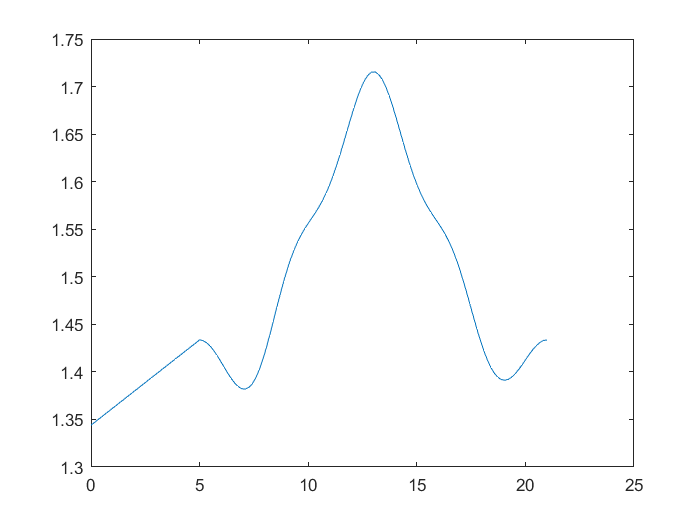


%theta_2a = -acos((px.^2+py.^2-d1^2-d2^2)/(2*d1*d2));
% omega_2a = diff(theta_2a,t);
% alpha_2a = diff(omega_2a,t);

%theta_1a = atan(py/px) - atan(d2.*sin(theta_2a)/(d1+d2.*cos(theta_2a)));
% omega_1a = diff(theta_1a,t);
% alpha_1a = diff(omega_1a,t);

theta_1a=linspace(theta_1_home,theta_1e(1),pa);
theta_2a=linspace(theta_2_home,theta_2e(1),pa);
traye_1=[theta_1a,theta_1e];
plot(tie,traye_1)

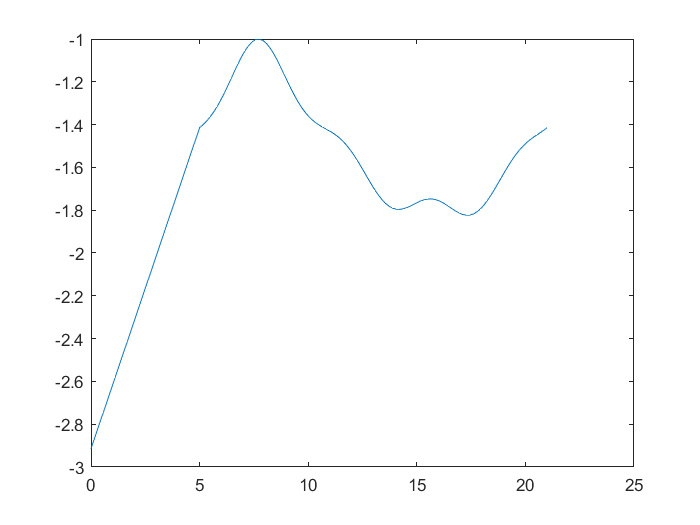

traye_2=[theta_2a,theta_2e];
plot(tie,traye_2)

## Gráficas

## x

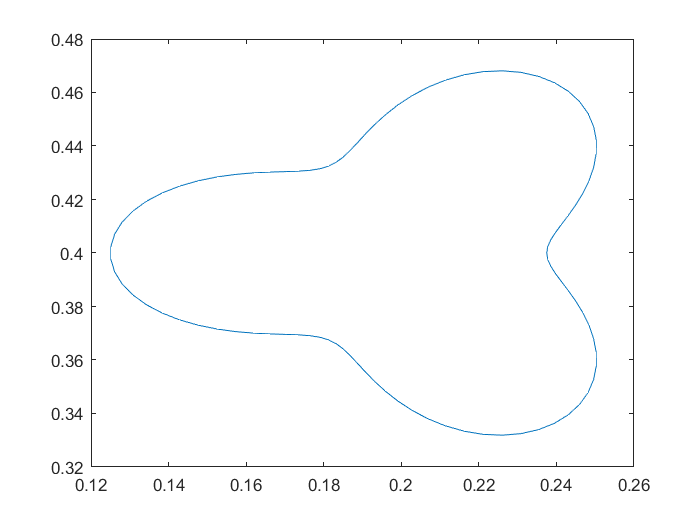

plot(eval(x),eval(y))

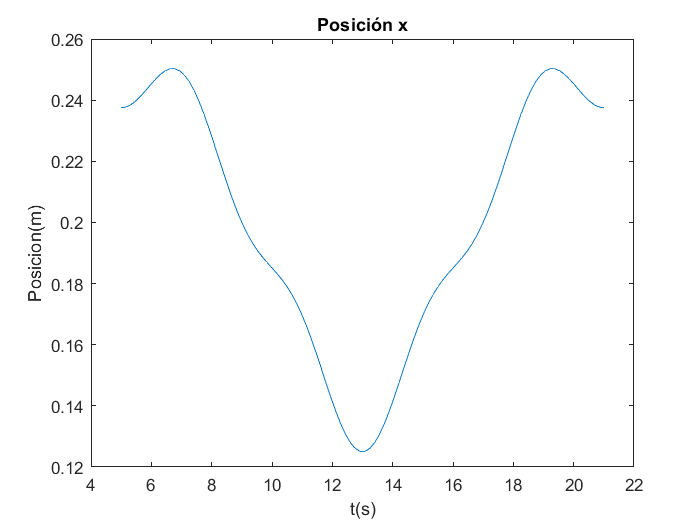

%Posición x
figure()
plot(t,xe)
title('Posición x')
xlabel('t(s)') 
ylabel('Posicion(m)')

%Velocidad x
% figure()
% plot(t,eval(v_x))
% title('Velocidad x')
% xlabel('t(s)') 
% ylabel('Velocidad(m/s)')
%Aceleración x
% figure()
% plot(t,eval(a_x))
% title('Aceleración x')
% xlabel('t(s)') 
% ylabel('Aceleración(m/s^2)')

## y

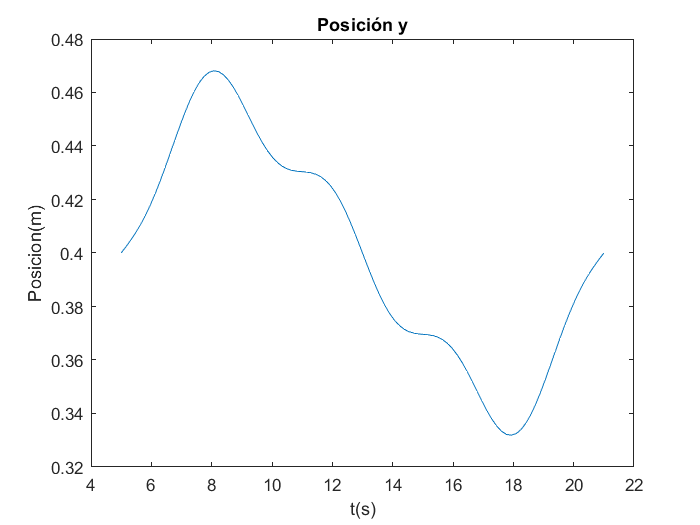

%Posición y
figure()
plot(t,ye)
title('Posición y')
xlabel('t(s)') 
ylabel('Posicion(m)')

%Velocidad y
% figure()
% plot(t,eval(v_y))
% title('Velocidad y')
% xlabel('t(s)') 
% ylabel('Velocidad(m/s)')
%Aceleración y
% figure()
% plot(t,eval(a_y))
% title('Aceleración y')
% xlabel('t(s)') 
% ylabel('Aceleración(m/s^2)')

## Joint 2

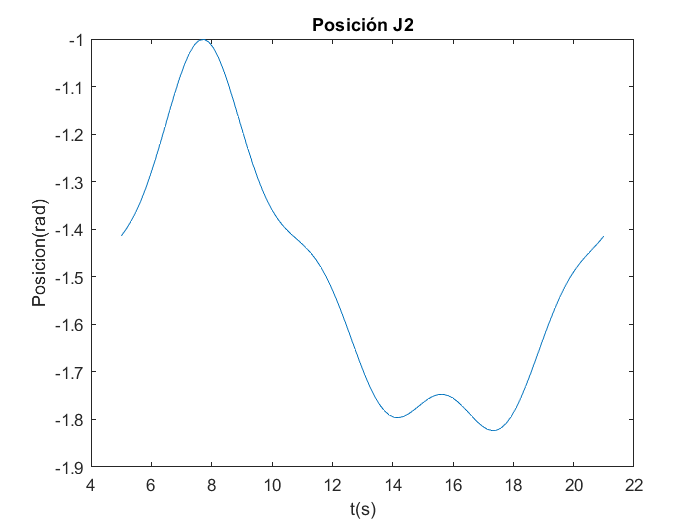

%Posición J2
figure()
plot(t,eval(theta_2))
title('Posición J2')
xlabel('t(s)') 
ylabel('Posicion(rad)')

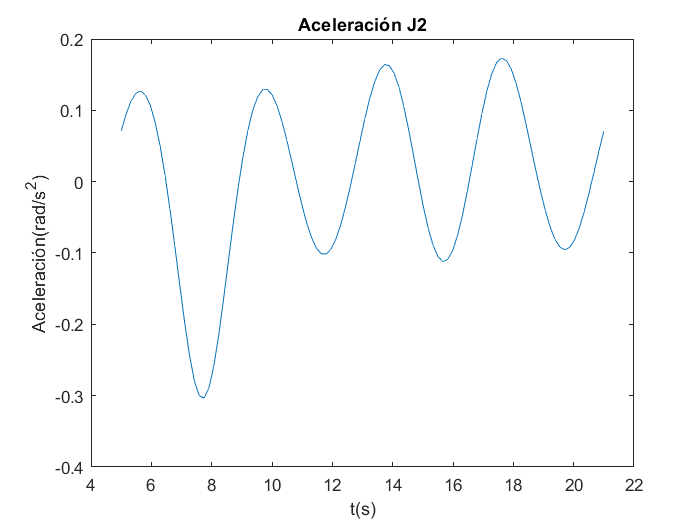

%Velocidad J2
% figure()
% plot(t,eval(omega_2))
% title('Velocidad J2')
% xlabel('t(s)') 
% ylabel('Velocidad(rad/s)')
%Aceleración J2
% figure()
plot(t,eval(alpha_2))
title('Aceleración J2')
xlabel('t(s)') 
ylabel('Aceleración(rad/s^2)')

## Joint 1

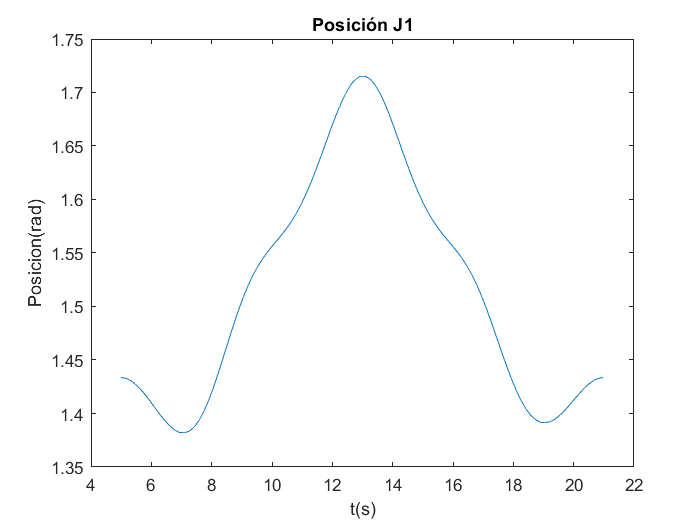

%Posición J1
figure()
plot(t,eval(theta_1))
title('Posición J1')
xlabel('t(s)') 
ylabel('Posicion(rad)')

%Velocidad J1
% figure()
% plot(t,eval(omega_1))
% title('Velocidad J1')
% xlabel('t(s)') 
% ylabel('Velocidad(rad/s)')
%Aceleración J1
% figure()
% plot(t,eval(alpha_1))
% title('Aceleración J1')
% xlabel('t(s)') 
% ylabel('Aceleración(rad/s^2)')

## Velocidad lineal

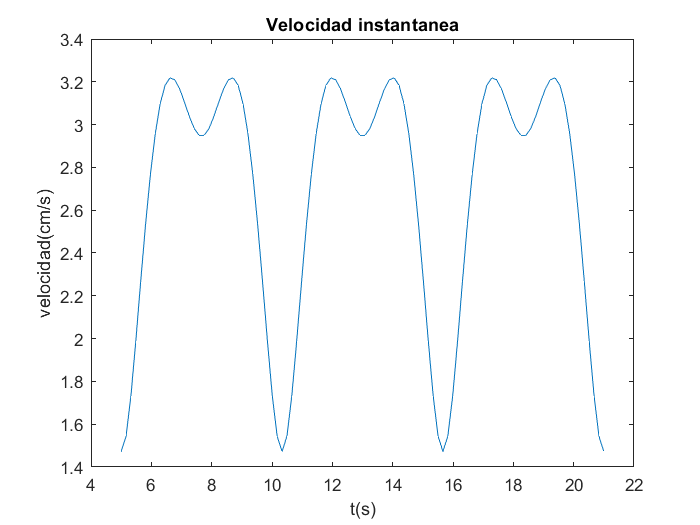

figure()
plot(t,eval(v)*100)
title('Velocidad instantanea')
xlabel('t(s)') 
ylabel('velocidad(cm/s)')

## Torques

## M2

g=9.81;
J2=m2*(d2^2)/3

J2 = 3.2985e-04

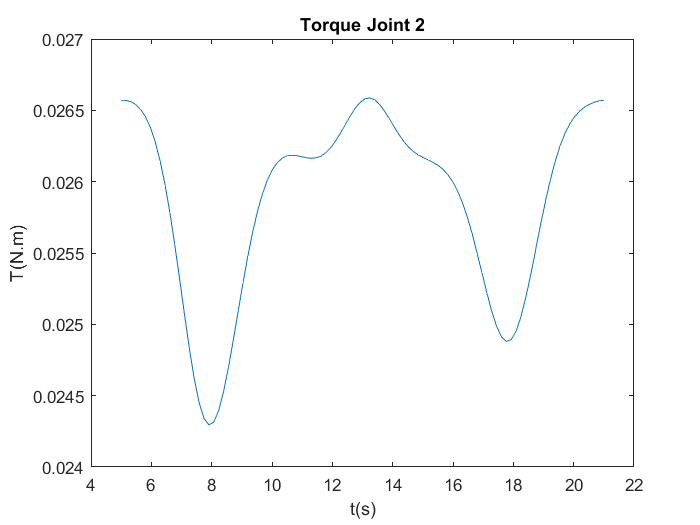

T_in2=J2*alpha_2;
T_g2=(m2*g*d2*cos(theta_1+theta_2))/2;
T_m2=T_in2+T_g2;
figure()
plot(t,eval(T_m2))
title('Torque Joint 2')
xlabel('t(s)') 
ylabel('T(N.m)')

Torque maximo M2

T_m2_eva=eval(T_m2);
T_m2_max=max(T_m2_eva)

T_m2_max = 0.0266

Torque RMS M2

T_m2_rms=sqrt(dt*sum(T_m2_eva.^2)/T)

T_m2_rms = 0.0259

## M1

mm2=0.043;
mst2=0.0879;

Je1=m1*(d1^2)/3;
Jm2=mm2*(d1^2);
Jst2=mst2*(d1^2);
Je2=max(eval(m2*(d1^2+(d2/2)^2-d1*d2*cos(pi-theta_1))));
%Je2=max(eval(Je2_ne))
J1=Je1+Jm2+Jst2+Je2

J1 = 0.0314

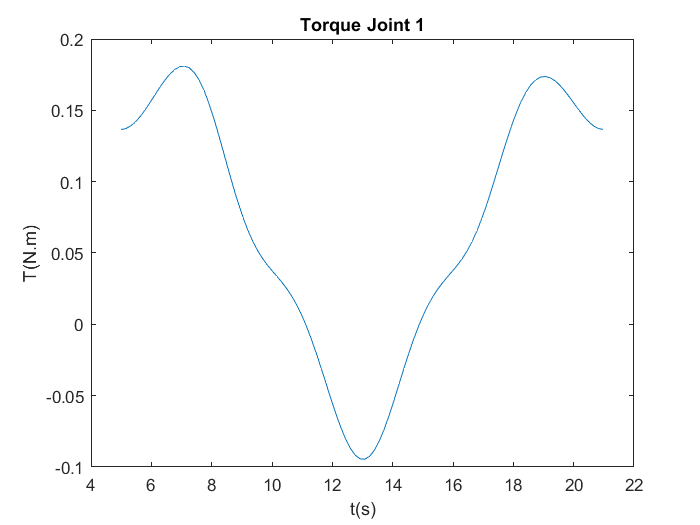

T_in1=J1*alpha_1;
T_g1=g*(((d1*cos(theta_1))*((m1/2)+mm2+mst2+m2))+(m2*d2*cos(theta_1+theta_2)/2));
T_m1=T_in1+T_g1;
figure()
plot(t,eval(T_m1))
title('Torque Joint 1')
xlabel('t(s)') 
ylabel('T(N.m)') 

Torque maximo M2

T_m1_eva=eval(T_m1);
T_m1_max=max(T_m1_eva)

T_m1_max = 0.1810

Torque RMS M2

T_m1_rms=sqrt(dt*sum(T_m1_eva.^2)/T)

T_m1_rms = 0.1129

# Seleccion de motor

## Joint 2

### DC022C -1

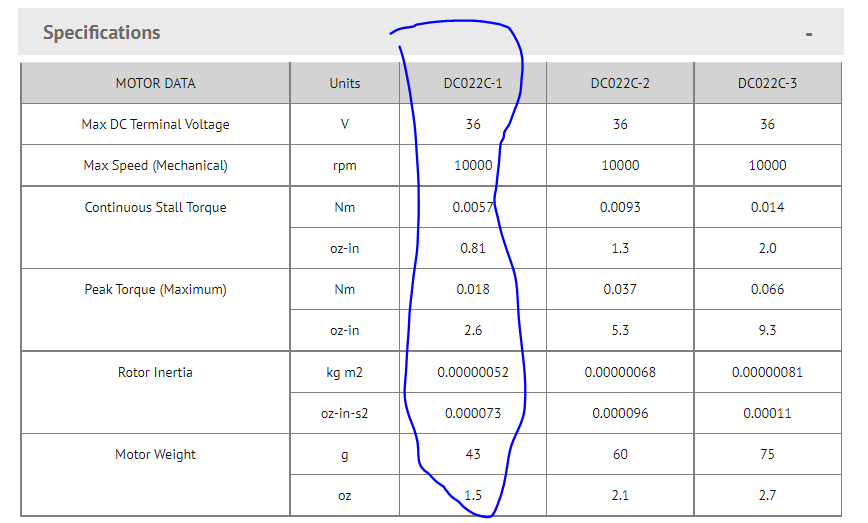

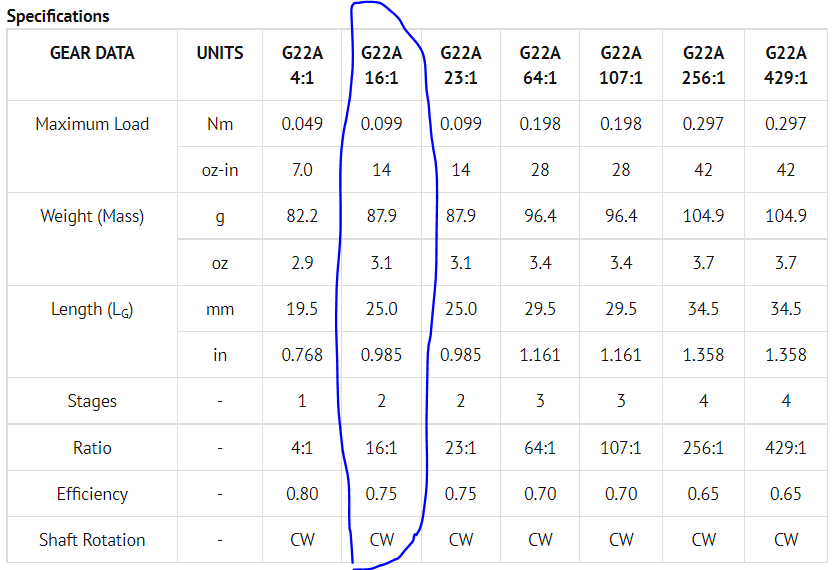

J_rotor=0.00000052;%kgm2
N=16%gearbox

N = 16

IR=J2/(J_rotor*N^2)

IR = 2.4779

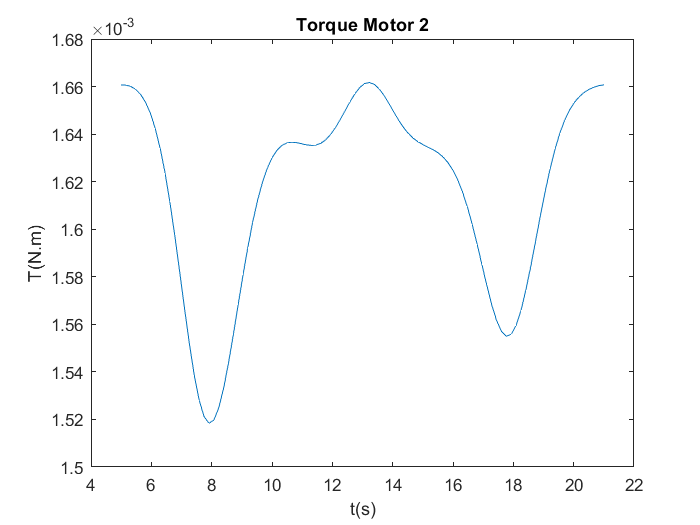

figure()
plot(t,eval(T_m2)/N)
title('Torque Motor 2')
xlabel('t(s)') 
ylabel('T(N.m)')

Torque maximo M2 con stp

T_m2_eva=eval(T_m2)/N;
T_m2_max=max(T_m2_eva)

T_m2_max = 0.0017

Torque RMS M2 con stp

T_m2_rms=sqrt(dt*sum(T_m2_eva.^2)/T)

T_m2_rms = 0.0016

Motor

T_m_pico=0.018; %Nm
T_m_cont=0.0057;%Nm

Velovidad con stp

velocidad_maxima_motor=10000;%rpm
vel_max_mot_rad=velocidad_maxima_motor*2*pi/(60*N)

vel_max_mot_rad = 65.4498

v_max_j2=max(eval(omega_2))

v_max_j2 = 0.2210

Funciona?

works=T_m_pico>=T_m2_max & T_m_cont>=T_m2_rms & IR<=15 &v_max_j2<=vel_max_mot_rad

works = logical
   1


## Joint 1

### DC022C -1

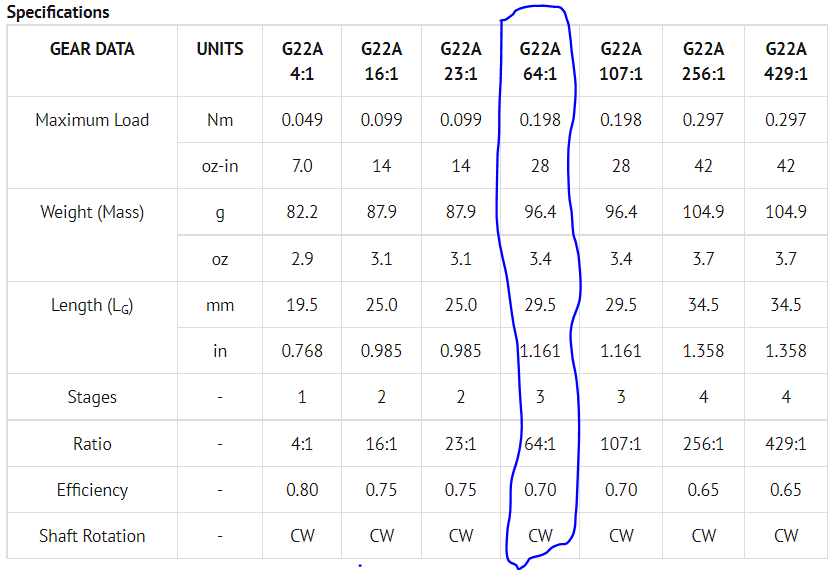

J_rotor=0.00000052;%kgm2
N=64 %gearbox

N = 64

IR1=J1/(J_rotor*N^2)

IR1 = 14.7643

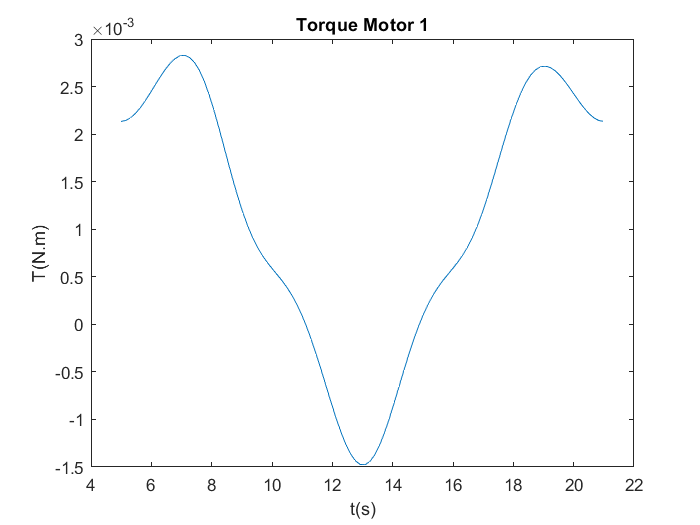

figure()
plot(t,eval(T_m1)/N)
title('Torque Motor 1')
xlabel('t(s)') 
ylabel('T(N.m)')

Torque maximo M1 con stp

T_m1_eva=eval(T_m1)/N;
T_m1_max=max(T_m1_eva)

T_m1_max = 0.0028

Torque RMS M1 con stp

T_m1_rms=sqrt(dt*sum(T_m1_eva.^2)/T)

T_m1_rms = 0.0018

Motor

T_m_pico=0.018; %Nm
T_m_cont=0.0057;%Nm

Velovidad con stp

velocidad_maxima_motor=10000;%rpm
vel_max_mot_rad=velocidad_maxima_motor*2*pi/(60*N)

vel_max_mot_rad = 16.3625

v_max_j1=max(eval(omega_1))

v_max_j1 = 0.0902

Funciona?

works=(T_m_pico>=T_m1_max & T_m_cont>=T_m1_rms & IR1<=15 & v_max_j1<=vel_max_mot_rad)

works = logical
   1


theta_1e=eval(theta_1);
theta_2e=eval(theta_2);
